# My Quiz Notes

## Baxter Robot


close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_baxter;
right.base %location of the left arm in a 4x4 matrix

ans =     0.7071    0.7071         0    0.0635
   -0.7071    0.7071         0   -0.2597
         0         0    1.0000    0.1190
         0         0         0    1.0000


left.base %location of the right arm

ans =     0.7071   -0.7071         0    0.0646
    0.7071    0.7071         0    0.2586
         0         0    1.0000    0.1190
         0         0         0    1.0000



qRight = [0,3*pi/8,0,0,0,0,-3*pi/4]

qRight =          0    1.1781         0         0         0         0   -2.3562


trRight = right.fkine(qRight)

trRight =    -0.0381   -0.9619    0.2706    0.3362
   -0.9619   -0.0381   -0.2706   -0.5323
    0.2706   -0.2706   -0.9239   -0.5817
         0         0         0    1.0000




x1 = left.base(1,4)

x1 = 0.0646

y1 = left.base(2,4)

y1 = 0.2586

z1 = left.base(3,4)

z1 = 0.1190

dist = sqrt((x1-trRight(1,4))^2 + (y1-trRight(2,4))^2 + (z1-trRight(3,4))^2)

dist = 1.0910



close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_baxter


qLeft = [0,-pi/2,0,0,6*pi/8,0,0]

qLeft =          0   -1.5708         0         0    2.3562         0         0


qRight = [0,3*pi/8,0,0,0,0,-3*pi/4]

qRight =          0    1.1781         0         0         0         0   -2.3562



trLeft = left.fkine(qLeft) % Gets the end effector's position

trLeft =    -1.0000   -0.0000   -0.0000    0.1522
    0.0000   -1.0000         0    0.3562
         0         0    1.0000    1.4070
         0         0         0    1.0000


trRight = right.fkine(qRight)

trRight =    -0.0381   -0.9619    0.2706    0.3362
   -0.9619   -0.0381   -0.2706   -0.5323
    0.2706   -0.2706   -0.9239   -0.5817
         0         0         0    1.0000



dist = sqrt((trLeft(1,4)-trRight(1,4))^2 + (trLeft(2,4)-trRight(2,4))^2 + (trLeft(3,4)-trRight(3,4))^2)

dist = 2.1859

### Practice Question 1 - Distance between the base of two arms

#### Create a Baxter Robot


close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_baxter;


Arm models are called left and right.

Determine the **distance** between the 'base' (where the two arms are mounted) of the two arms.

right.base %location of the left arm in a 4x4 matrix

ans =     0.7071    0.7071         0    0.0635
   -0.7071    0.7071         0   -0.2597
         0         0    1.0000    0.1190
         0         0         0    1.0000


left.base %location of the right arm

ans =     0.7071   -0.7071         0    0.0646
    0.7071    0.7071         0    0.2586
         0         0    1.0000    0.1190
         0         0         0    1.0000



x1 = right.base(1,4) % due to the matrix, the xyz positions are in the 4th coumn, 1st, 2nd, and 3rd row respectively

x1 = 0.0635

x2 = left.base(1,4)

x2 = 0.0646

y1 = right.base(2,4)

y1 = -0.2597

y2 = left.base(2,4)

y2 = 0.2586

z1 = right.base(3,4)

z1 = 0.1190

z2 = left.base(3,4)

z2 = 0.1190

dist = sqrt((x1-x2)^2 + (y1-y2)^2 + (z1-z2)^2)

dist = 0.5182

### Practice Question 2

#### Create a Baxter Robot


close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_baxter;

What can you say about the ikine solution attempting to get to tr = left.fkine(qr) when you use qr*1.1 as the initial guess and you **do not** mask off the roll, pitch, and yaw (i.e. by passing [1,1,1,1,1,1] to ikine for the mask)

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_baxter;
q = zeros(1,7)

q =      0     0     0     0     0     0     0


tr = left.fkine(qr) % transform that shows the end effector orientation for specified joint angles qr.

tr =     0.7071    0.7071         0    0.1693
   -0.7071    0.7071         0    0.2515
         0         0    1.0000    1.4070
         0         0         0    1.0000


                        % qr is a joint angle configuration where y and z are -90 degrees.
                        

Un-Masked

qm = left.ikine(tr,q,[1 1 1 1 1 1]) % diverges too many times to calculate

Masked

qi = left.ikine(tr,q,[1 1 1 0 0 0])

ti = left.fkine(qi)
tm = left.fkine(qm)

### Practice Question 3 - Distance between End Effectors

Create a baxter robot with mdl_baxter

Given the arm models are called 'left' and 'right', determine the distance between the two end effectors when:

    qLeft = [pi/10, 0, 0, 0, 0, 0, pi/10]

    qRight = [-pi/10, 0, 0, 0, 0, 0, -pi/10]

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_baxter

qLeft = [0,-pi/2,0,0,6*pi/8,0,0]

qLeft =          0   -1.5708         0         0    2.3562         0         0


qRight = [0,3*pi/8,0,0,0,0,-3*pi/4]

qRight =          0    1.1781         0         0         0         0   -2.3562



%qLeft = [pi/10, 0, 0, 0, 0, 0, pi/10] % joint configuration for the left arm
%qRight = [-pi/10, 0, 0, 0, 0, 0, -pi/10] % joint configuration for the right arm

trLeft = left.fkine(qLeft) % Gets the end effector's position

trLeft =    -1.0000   -0.0000   -0.0000    0.1522
    0.0000   -1.0000         0    0.3562
         0         0    1.0000    1.4070
         0         0         0    1.0000


trRight = right.fkine(qRight)

trRight =    -0.0381   -0.9619    0.2706    0.3362
   -0.9619   -0.0381   -0.2706   -0.5323
    0.2706   -0.2706   -0.9239   -0.5817
         0         0         0    1.0000



dist = sqrt((trLeft(1,4)-trRight(1,4))^2 + (trLeft(2,4)-trRight(2,4))^2 + (trLeft(3,4)-trRight(3,4))^2)

dist = 2.1859

## Collision

### Practice Question 5 - collision of robot arms

Create a hyper redundant planart manipulator with mdl_hyper2d.

Which Pose would be in self collision? 

*Edit the variable q to the different positions of the arms.*

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_hyper2d
q=[pi, pi/2, -pi/2, -pi/2, -pi/2, pi/2, -pi/2, pi/2, -pi/3, -pi/3] % enter the joint positions here or..

q =     3.1416    1.5708   -1.5708   -1.5708   -1.5708    1.5708   -1.5708    1.5708   -1.0472   -1.0472


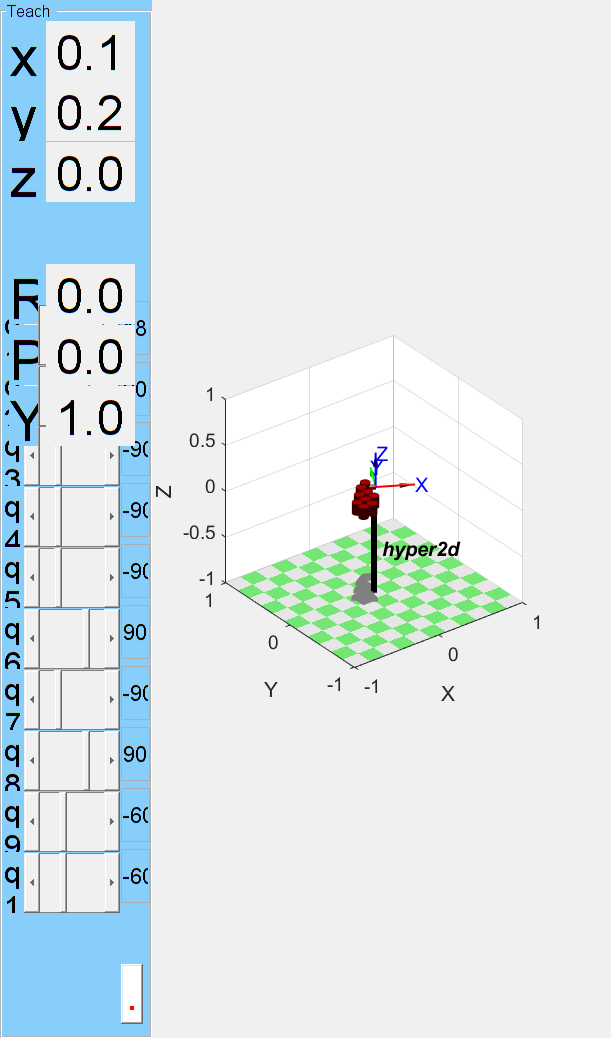

h2d.teach(q) % ..edit the joint positions on the model

## Local vs Global Coordinate Frame

### Practice Question 6 - position of object with respect to end effector

create a puma 560 (mdl_puma560)

Assume its bolted on a table 0.8m off the ground

q = [-90, 45, 45, 0, 45, 0] degrees.

A ball has a global transform transl(0.5, 0, 0.6) * trot(pi/2)

What is the **balls position** with respect to the **end effectors coordinate frame**

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_puma560

Move the base off the ground

p560.base = transl(0,0,0.8)

 
p560 = 
 
Puma 560 (6 axis, RRRRRR, stdDH, fastRNE)                                     
 viscous friction; params of 8/95;                                            
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|          0|          0|      1.571|          0|             
|  2|         q2|          0|     0.4318|          0|          0|             
|  3|         q3|       0.15|     0.0203|     -1.571|          0|             
|  4|         q4|     0.4318|          0|      1.571|          0|             
|  5|         q5|          0|          0|     -1.571|          0|             
|  6|         q6|          0|          0|          0|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                        

Joint positions

%q = deg2rad( [0, 45, 45, 0, 45, 0]) % Set q as per the question
% q = deg2rad([-90,45,45,0,45,0])
q = deg2rad([0, 45, 45, 45, 45, 45]);

Get the transform (pose) of the end effector based on the joint positions q

tr = p560.fkine(q) 

tr =    -0.5000    0.5000   -0.7071   -0.1265
    0.8536    0.1464   -0.5000   -0.1500
   -0.1464   -0.8536   -0.5000    1.1256
         0         0         0    1.0000


p560.teach(q)
hold on
axis equal

Set the balls pose and plot as a transform

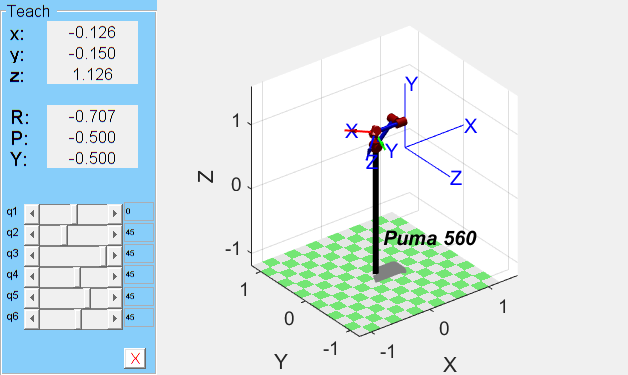

ball = transl(0.5,0,0.6) * trotx(pi/2);

trplot(ball)

% hold off
% qball = p560.ikine(ball)
% p560.plot(qball)

(inverse of end effector frame)*ball = balls pose from end effector.

local = inv(tr)*ball 

local =    -0.5000   -0.1464   -0.8536   -0.1082
    0.5000   -0.8536   -0.1464    0.7839
   -0.7071   -0.5000    0.5000   -0.2552
         0         0         0    1.0000


### Question 7 - Equal Poses

Create a puma 560

#### Part 1 - Will the following be true?

fkine(p560,ikine(p560,fkine(p560,[pi/4,0,0,0,0,0]))) == fkine(p560,[pi/4,0,0,0,0,0])

#### Part 2 - Will the following be true?

fkine(p560,ikine(p560,fkine(p560,[-pi/4,0,0,0,0,0]),[-pi/4,0,0,0,0,0])) == fkine(p560,[-pi/4,0,0,0,0,0])

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_puma560

Part 1

part1a = fkine(p560,ikine(p560,fkine(p560,[pi/4,0,0,0,0,0])))
part1b = fkine(p560,[pi/4,0,0,0,0,0])

if part1a ~= part1b
    disp('false')
else
    disp('true')
end

Part 2

part2a = fkine(p560,ikine(p560,fkine(p560,[pi/4,0,0,0,0,0]),[pi/4,0,0,0,0,0])) 
part2b = fkine(p560,[pi/4,0,0,0,0,0])
if part2a ~= part2b
    disp('false')
else
    disp('true') 
end

### Question 8 - Jacobian

Create a puma 560 on the floor

Move to the middle of its range: q = [p560.qlim(:,1) + (p560.qlim(:,2) - p560.qlim(:,1))/2']

Compute the jacobian at this pose i.e. p560.jacob0(q)

Based on the matrix, what would you say about the robot at this pose. Note, rows are x,y,z,r,p,y

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_puma560


q = pi/8*ones(1,6)

q =     0.3927    0.3927    0.3927    0.3927    0.3927    0.3927


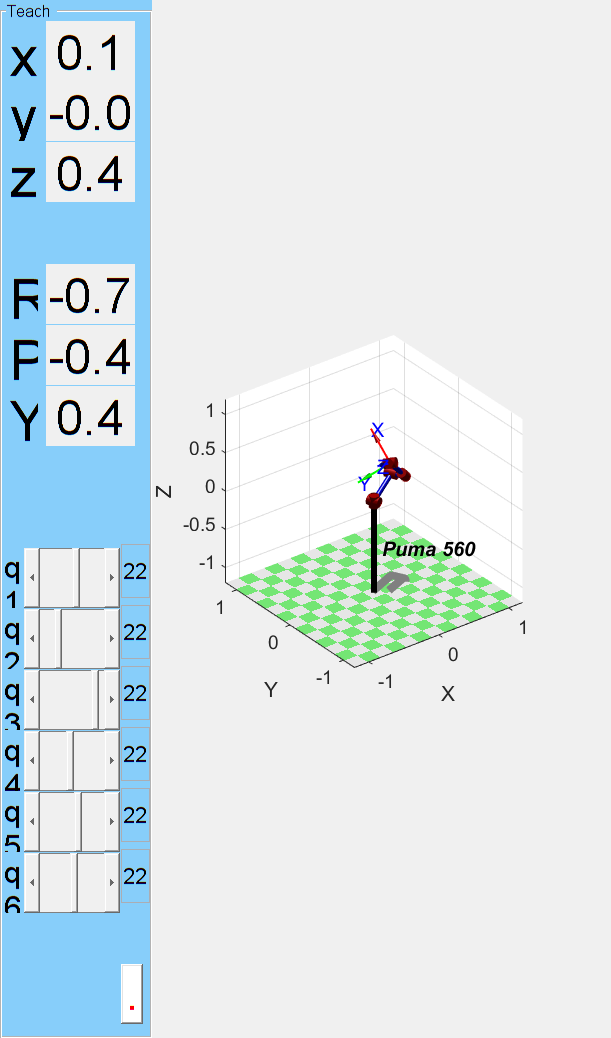

%qmiddle = [p560.qlim(:,1) + (p560.qlim(:,2)-p560.qlim(:,1))/2]';
p560.teach(q)

p560.jacob0(q) %the robot has become 5dof because two joints now rotate around the same axis.

ans =     0.0973   -0.4480   -0.2953         0         0         0
    0.1572   -0.1856   -0.1223         0         0         0
    0.0000    0.1080   -0.2910         0         0         0
   -0.0000    0.3827    0.3827   -0.6533    0.6036   -0.7785
    0.0000   -0.9239   -0.9239   -0.2706   -0.7500   -0.4810
    1.0000    0.0000    0.0000    0.7071    0.2706    0.4033


q(1,3) = q(1,3)*pi/4

q =     0.3927    0.3927    0.3084    0.3927    0.3927    0.3927


p560.jacob0(q)

ans =     0.0866   -0.4696   -0.3169         0         0         0
    0.1830   -0.1945   -0.1313         0         0         0
   -0.0000    0.1359   -0.2630         0         0         0
         0    0.3827    0.3827   -0.5960    0.6237   -0.7442
    0.0000   -0.9239   -0.9239   -0.2469   -0.7417   -0.4668
    1.0000    0.0000    0.0000    0.7641    0.2469    0.4779


### Question 9 - End-effector distance to the floor

Create a puma 560

Assume its bolted to the floor. Given the arm model is called 'p560', determine the distance from the end effector to the floor when 

q = [pi/10, 0, 0, 0, 0, 0]

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_puma560

Joint configurations q

q = [pi/10,0,0,0,0,0]
tr = p560.fkine(q)
p560.plot(q)


Distance to the floor

tr(3,4)


### Question 10

puma560

Assume bolted 0.8m off the ground.

Determine end effector position to the floor when q = [0, 0, pi/10, 0, 0, 0]

close all
set(0,'DefaultFigureWindowStyle','docked')
clear
clc
mdl_puma560
q = [0,0,pi/10,0,0,0]

p560.base = transl(0,0,0.4)
tr = p560.fkine(q)
p560.teach(q)
axis equal

Distance to the floor

tr(3,4)
